# Function

type myFunction.m

function [y,dydx1] = myFunction(x1)

y = sin((pi/4)*norm(x1)^2);
[dydx1] = dlgradient(y,x1);

end


x0 = 2.0 * ones(2,1);
f =@(x) sin(0.25 * pi * sum(x .^ 2));
dlgradf =@(x) dlgradient(f(x), x);
grad_f =@(x) dlfeval(dlgradf, dlarray(x));

v = [];
v = grad_f(x0);

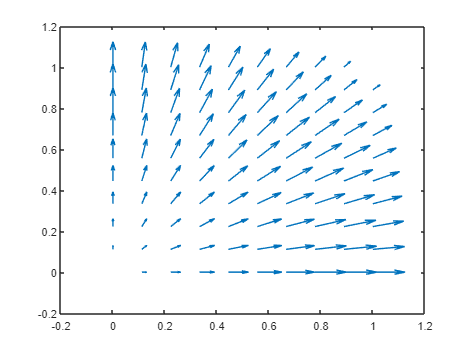

[X1, X2] = meshgrid(linspace(0,1,10));


Y = zeros(size(X1));
DYDX1 = zeros(size(X1));
DYDX2 = zeros(size(X2));

for i = 1:length(Y)
    for j = 1:length(Y)
        v = [];
        v = grad_f(dlarray([X1(i,j),X2(i,j)]));
        DYDX1(i,j) = v(1);
        DYDX2(i,j) = v(2);
    end
end

quiver(X1,X2,DYDX1,DYDX2)